# Robotics 2 - Final Exam  - July 11, 2018

## Exercise 1

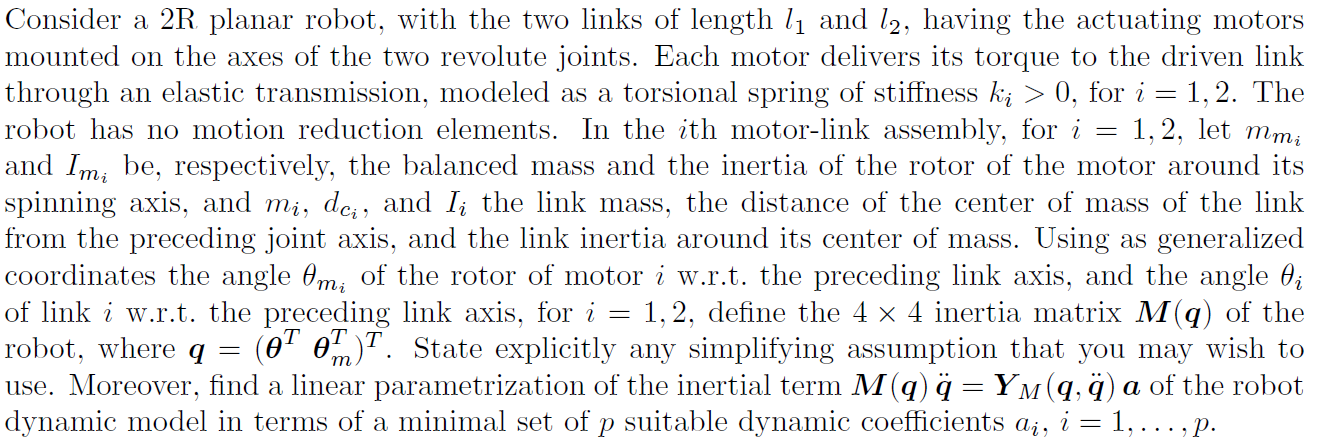

## my aproach

clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
sigma = [0,0];
n = length(sigma);
% t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');

q = sym('theta_', [n 1],'real');
q_dot = sym('theta_dot_', [n 1],'real');
q_ddot = sym('theta_ddot_', [n 1],'real');

%
dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l_', [n 1],'real');
m = sym('m_', [n 1],'real');
I = sym('I_', [n 1],'real');

% motor definitions
% q_m = sym('q_m_', [n 1],'real');
% q_dot_m = sym('q_dot_m_', [n 1],'real');
% q_ddot_m = sym('q_ddot_m_', [n 1],'real');

q_m = sym('theta_m_', [n 1],'real');
q_dot_m = sym('theta_dot_m_', [n 1],'real');
q_ddot_m = sym('theta_ddot_m_', [n 1],'real');


%
% dc = sym('dc_', [n 1],'real');

% l = sym('l_', [n 1],'real');
m_m = sym('m_m_', [n 1],'real');
I_m = sym('I_m_', [n 1],'real');


alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[g0,0,0]';

defining z struct

R2Robot=['rr';'xx';sigma]

R2Robot = 3×2 char array
    'rr'
    'xx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.m=m;
z.I=I;

z.q_m=q_m;
z.q_dot_m=q_dot_m;
z.q_ddot_m=q_ddot_m;
z.m_m=m_m;
z.I_m=I_m;


z.dc=dc;
z.methodD=1;
% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[];
% z.movingframes=[];
z.angle_=sym(zeros(1,n));
l_0=sym('l','real')

$$l\_0 = l$$

% z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary

% z.rcdefined=true;

z.ismotor=true;
z.motoronly=false;
z.vartoderivate="theta";

## axis offset

% 
% h=sym('h','real')
% %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]'%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=true
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
              

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{\theta }}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$Ti\_m = \frac{I_{m,1}\,{{\dot{\theta }}_{m,1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{\theta }}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(\theta_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{\theta }}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(\theta_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{\theta }}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$Ti\_m = \left(\begin{array}{cc} \frac{I_{m,1}\,{{\dot{\theta }}_{m,1}}^{2}}{2} & \frac{I_{m,2}\,{\left({\dot{\theta }}_{1}+{\dot{\theta }}_{m,2}\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{m,2}\,{{\dot{\theta }}_{1}}^{2}}{2} \end{array}\right)$$

$$M\_m = \left(\begin{array}{cc} I_{m,1} & 0\\ 0 & I_{m,2} \end{array}\right)$$

$$M\_total = \begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{m,2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{m,2}+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(\theta_{2}\right) & \sigma_{1} & 0 & I_{m,2}\\ \sigma_{1} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & I_{m,1} & 0\\ I_{m,2} & 0 & 0 & I_{m,2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} \end{array}$$

$$To\_derive = \left(\begin{array}{cc} -l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right) & -l_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right) & l_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} \theta_{1}\left(t\right)\\ \theta_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{1} & {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} & {\dddot{\theta }}_{1}\\ \theta_{2} & {\dot{\theta }}_{2} & {\ddot{\theta }}_{2} & {\dddot{\theta }}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{1} & {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} & {\dddot{\theta }}_{1}\\ \theta_{2} & {\dot{\theta }}_{2} & {\ddot{\theta }}_{2} & {\dddot{\theta }}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} \theta_{1} & {\dot{\theta }}_{1} & {\ddot{\theta }}_{1} & {\dddot{\theta }}_{1}\\ \theta_{2} & {\dot{\theta }}_{2} & {\ddot{\theta }}_{2} & {\dddot{\theta }}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}
M_total=Trans.M_total

$$M\_total = \begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{m,2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{m,2}+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(\theta_{2}\right) & \sigma_{1} & 0 & I_{m,2}\\ \sigma_{1} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & I_{m,1} & 0\\ I_{m,2} & 0 & 0 & I_{m,2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} \end{array}$$

## getting dynamics parameters

[Msubs, dynamicParamsReturn, a] = getDynamicParameters2(M_total,[q;z.q_m],[])

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$Msubs = \left(\begin{array}{cccc} a_{4}+2\,a_{5}\,\cos\left(\theta_{2}\right) & a_{1}+a_{5}\,\cos\left(\theta_{2}\right) & 0 & a_{3}\\ a_{1}+a_{5}\,\cos\left(\theta_{2}\right) & a_{1} & 0 & 0\\ 0 & 0 & a_{2} & 0\\ a_{3} & 0 & 0 & a_{3} \end{array}\right)$$

$$dynamicParamsReturn = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ I_{m,1}\\ I_{m,2}\\ I_{1}+I_{2}+I_{m,2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{m,2}\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2} \end{array}\right)$$

$$a = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$

## linear parametrization

YM = getLinearParametrization(Msubs*[q_ddot;z.q_ddot_m], a)

$$YM = \left(\begin{array}{ccccc} {\ddot{\theta }}_{2} & 0 & {\ddot{\theta }}_{m,2} & {\ddot{\theta }}_{1} & 2\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{2}\right)+{\ddot{\theta }}_{2}\,\cos\left(\theta_{2}\right)\\ {\ddot{\theta }}_{1}+{\ddot{\theta }}_{2} & 0 & 0 & 0 & {\ddot{\theta }}_{1}\,\cos\left(\theta_{2}\right)\\ 0 & {\ddot{\theta }}_{m,1} & 0 & 0 & 0\\ 0 & 0 & {\ddot{\theta }}_{1}+{\ddot{\theta }}_{m,2} & 0 & 0 \end{array}\right)$$

## arci approach

% 
% clear ;clc;
% sigma = [0,0]; % 0: Revolute, 1:Prismatic
% n = length(sigma);
% 
% % Link parameters
% q = sym('q', [1,n]).' ;
% qd = sym('qd', [1,n]).' ;
% l = sym('l', [1,n]).' ;
% m = sym('m', [1,n]).' ;
% d = sym('d', [1,n]).' ;
% I = sym('I', [1,n]).' ;
% qdd = sym('qdd',[1,n]).'
% 
% % Motor parameters
% qm = sym('qm', [1,n]).' ;
% qdm = sym('qdm', [1,n]).' ;
% lm = sym('lm', [1,n]).' ;
% mm = sym('mm', [1,n]).' ;
% dm = sym('dm', [1,n]).' ;
% Im = sym('Im', [1,n]).' ;
% qddm = sym('qddm',[1,n]).'
% 

% dm = sym('dm', [1,n])
% 
% [dhTable, Msubs, dynParams, a]  = getRR_Robot()

% % Just replace to distinguish l from I (Inertia)
% %dhTable = subs(dhTable,  sym('l', [1,n]).', L)

% % dhTable

### Computation of Kinetic Energy

% [KE_Links , Tlinks] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)
% [KE_Motors , Tmotors] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,1,qdm)

### Computation of Inertia matrix

% KE_Total = KE_Links + KE_Motors
% M = getInertiaMatrixFromKE(KE_Total,[qd;qdm])

% [Msubs, dynamicParamsReturn, a] = getDynamicParameters(M,[q;qm],[])

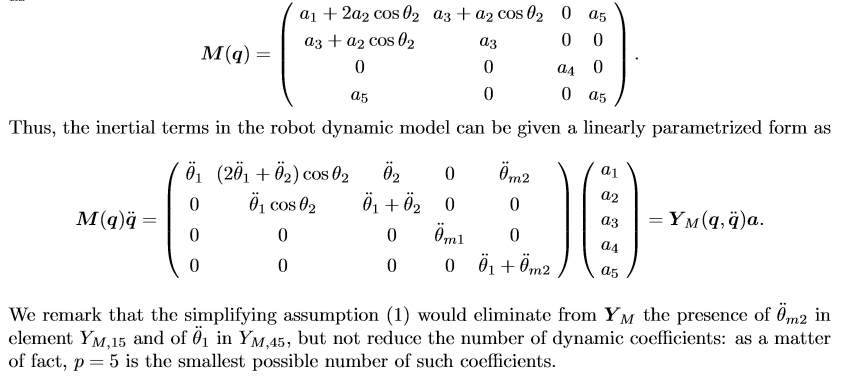

###  Computation of Linear Parametrization

% % YM = getLinearParametrization(Msubs, [qdd;qddm], a)
%  YM =getLinearParametrization(Msubs*[qdd;qddm], a)

## Exercise 2

**This is incomplete!!! The SNS algoruth has to be corrected and completed.**

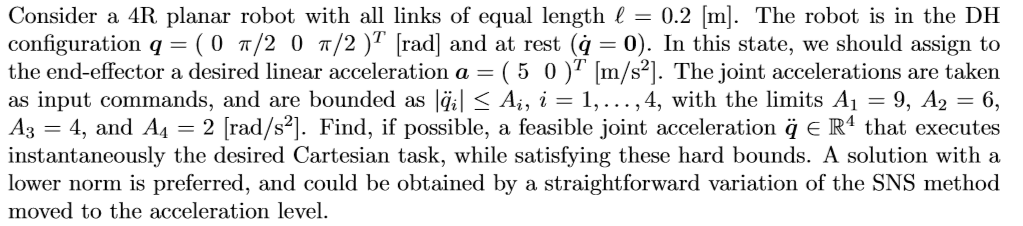

## my approach

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';
% 

% R2Robot=['rrrr';'xxxx';sigma]  ;     
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.xyonly=true;
% 

% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% % VarShortRobot.M
% % angle_desired=[0,alpha_angle]
% % [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I,1,[],[],'alpha',false,angle_desired)
% % [C,cac,Csubs,S] = getCs(M,q,qd)
% % 
% % % [C,cac,Csubs] = getCs(Msubs,q',qd')
% % u =simplify( M*qdd + cac)

% vars2replace=[l;q]
% l0_=0.2;
% q_=[0,pi/2,0,pi/2]'; 
% l_=[l0_,l0_,l0_,l0_]';
% 
% vars2replace_=[l_;q_]
% 
% J_=subs(J,vars2replace,vars2replace_)
% 

## sns

% 
% V_=[5,0]'
% q_dMax_ = [9,6,4,2] % Maximum acceleration constraints of joints
% % 
% q_dMaxTemp_ = q_dMax_ % Maximum acceleration constraints of joints
% 
% vpa(J_)
% rank_J_=rank(J_)
% rank_V_=rank(V_)
% if(rank_J_<2)
% disp("Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!")
% if(rank_J_==rank_V_)
% disp("but The rank is inside of rank V_ all are: "+rank_J_)
% disp("BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!")
% end
% end

% abs_on=true;
% autodetectsign=true
% [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)
% 
% [qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## arci aproach

% 
% % disp('** Exercise 2')
% % clear ;clc;
% % sigma = [0,0,0,0]; % 0: Revolute, 1:Prismatic
% % n = length(sigma);
% % 
% % % Link parameters
% % q = sym('q', [1,n]).' ;
% % qd = sym('qd', [1,n]).' ;
% % l = sym('l') ;
% % m = sym('m', [1,n]).' ;
% % d = sym('d', [1,n]).' ;
% % I = sym('I', [1,n]).' ;
% % qdd = sym('qdd',[1,n]).'
% % 
% % dhTable = [0, l, 0, q(1);
% %            0, l, 0, q(2);
% %            0, l, 0, q(3);
% %            0, l, 0, q(4)]
% % 
% % q0 = [0, pi/2, 0, pi/2].'; % initial configuration.
% % qd0 = [0,0,0,0].'; % Initial velocity at rest.
% % 

% % % Calculate the Jacobian (Rotational)
% % [Jp, Jo] = getJacobian(dhTable,sigma,'alpha')
% % %Jac = [Jp;Jo]
% % %Eliminate the zero rows, which represent the unused variables
% % Jp = Jp(~all(Jp == 0,2),:)
% % 
% % J = subs(Jp, [q; l], [q0 ; 0.2])

% % SNS_sol(J, xdd, A)

% % % Acceleration limits
% % A = [9,6,4,2];
% % 
% % % SNS (Saturation on Null Space)
% % xdd= [5,0].'
% % qddPS = eval(pinv(J))*xdd
% % maxvalue = 1
% % qddstar = qddPS
% % qdd_sns = qddPS
% % while maxvalue > 0
% %     [maxvalue, maxindex] = max(abs(qddstar)-abs(A')) % The positive values are violating the limit. We take the highest one.
% %     if (maxvalue > 0) % if there is an exceeding value
% %         s = A(1)/qddstar(maxindex)    
% %         %xdot_sns  = xdot - J(:,maxindex)* sign(qdotPS(maxindex))*V(maxindex)
% %         %Same as 
% %         xdot_sns  = xdd - abs(J(:,maxindex)*A(maxindex));
% %         Jtemp = J
% %         Jtemp(:,maxindex) = [];
% %         qdot_components = eval(pinv(Jtemp)*xdot_sns).' 
% %         qdd_sns = [qdot_components(1:maxindex-1), A(maxindex), qdot_components(maxindex:end)]
% %         qddstar = qdd_sns;
% %     else
% %         disp("[INFO] No values are exceeding the limits.")
% %         disp('Result:')
% %         qddstar
% %     end
% % end

## Exercise 3